% 定义保护区对象
protectionZone1 = ProtectionZone("保护区1", [0, 0], 30, 3,10);
protectionZone2 = ProtectionZone("保护区2", [500, 500], 10,2, 10);
protectionZone3 = ProtectionZone("保护区3", [750, 200], 50, 1,10);
% 将保护区对象添加到集合中

protectionZones = {protectionZone1, protectionZone2,protectionZone3};
protectionZones

protectionZones = 1×3 cell 数组
    {1×1 ProtectionZone}    {1×1 ProtectionZone}    {1×1 ProtectionZone}


clear protectionZone1 protectionZone2 protectionZone3

% 初始化火力单元类型信息，并添加到火力单元类型集合中
% 火力类型1
fireunit1 = FireUnit("A", 8.5, 0.9, 100000, 5000, 20000, 100);
% 火力类型2
fireunit2 = FireUnit("B", 6.2, 0.75, 30000, 1000, 15000, 50);
% 火力类型3
fireunit3 = FireUnit("C", 5.8, 0.85, 20000, 500, 10000, 30);
% 创建火力单元类型集合
fireUnits = {fireunit1,fireunit2,fireunit3};
fireUnits

fireUnits = 1×3 cell 数组
    {1×1 FireUnit}    {1×1 FireUnit}    {1×1 FireUnit}


% 创建武器库对象
depot1_fires=[10,20,5];
depot1 = WeaponDepot("固定武器库", [100, 200], depot1_fires, 500, "正常");
depot2_fires=[5,10,5];
depot2 = WeaponDepot("临时存储点", [400, 500], depot2_fires, 50, "正常");
depots={depot1,depot2};
clear depot1_fires depot2_fires
depots

depots = 1×2 cell 数组
    {1×1 WeaponDepot}    {1×1 WeaponDepot}


% 初始化敌方目标类型
enemyUnit1 = EnemyUnit("弹道导弹", 10, 3000, 5, 2.5, true, "", 0, 0, 0);
enemyUnit2 = EnemyUnit("轰炸机", 8, 800, 10, 15, false, "空地导弹", 4, 500, 200);
enemyUnit3 = EnemyUnit("侦察机", 5, 2000, 15, 3, false, "炸弹", 2, 300, 100);
enemyUnit4 = EnemyUnit("运输机", 6, 700, 8, 10, false, "炸弹", 3, 250, 150);

% 将敌方目标类型添加到集合中
enemyUnitTypes = {enemyUnit1, enemyUnit2, enemyUnit3, enemyUnit4}

enemyUnitTypes = 1×4 cell 数组
    {1×1 EnemyUnit}    {1×1 EnemyUnit}    {1×1 EnemyUnit}    {1×1 EnemyUnit}


clear enemyUnit1 enemyUnit2 enemyUnit3 enemyUnit4

% 随机生成敌方单位，围绕保护区形成圆环
numEnemies = 30;
enemys = cell(numEnemies, 1);

for i = 1:numEnemies
    % 随机选择保护区
    zoneIdx = randi(length(protectionZones));
    selectedZone = protectionZones{zoneIdx};
    
    % 随机生成角度（0到2π）
    angle = rand() * 2 * pi;
    
    % 随机生成距离保护区边缘的距离
    distance = selectedZone.Size + (rand() * 3 + 1) * selectedZone.Size;
    
    % 根据极坐标计算X、Y坐标，围绕保护区
    x = selectedZone.Location(1) + distance * cos(angle);
    y = selectedZone.Location(2) + distance * sin(angle);
    z = randi([30, 100]); % Z坐标范围30到100
    
    % 随机选择敌方目标类型
    typeIdx = randi(length(enemyUnitTypes));
    selectedEnemyType = enemyUnitTypes{typeIdx};
    
    % 创建Enemy实例
    enemy = Enemy(...
        selectedEnemyType.Type, ...
        selectedEnemyType.Value, ...
        selectedEnemyType.Speed, ...
        selectedEnemyType.Altitude, ...
        selectedEnemyType.RCS, ...
        selectedEnemyType.IsMissile, ...
        selectedEnemyType.PayloadType, ...
        selectedEnemyType.PayloadQuantity, ...
        selectedEnemyType.Distance, ...
        selectedEnemyType.Height, ...
        x, y, z);
    
    % 添加到敌方目标集合
    enemys{i} = enemy;
end
enemys

enemys = 30×1 cell 数组
    {1×1 Enemy}
    {1×1 Enemy}
    {1×1 Enemy}
    {1×1 Enemy}
    {1×1 Enemy}
    {1×1 Enemy}
    {1×1 Enemy}
    {1×1 Enemy}
    {1×1 Enemy}
    {1×1 Enemy}
    {1×1 Enemy}
    {1×1 Enemy}
    {1×1 Enemy}
    {1×1 Enemy}
    {1×1 Enemy}
    {1×1 Enemy}


clear zoneIdx selectedZone angle distance x y z typeIdx selectedEnemyType enemy numEnemies

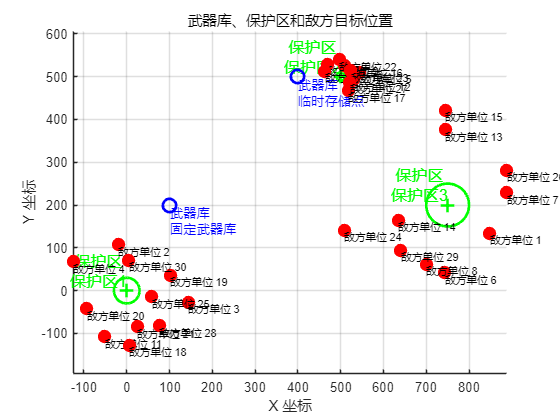

% 绘图展示武器库、保护区和敌方目标的位置
figure;
hold on;

% 绘制保护区
for i = 1:length(protectionZones)
    zone = protectionZones{i};
    % 绘制保护区边界（假设保护区是圆形）
    rectangle('Position', [zone.Location(1)-zone.Size, zone.Location(2)-zone.Size, 2*zone.Size, 2*zone.Size], ...
              'Curvature', [1, 1], 'EdgeColor', 'g', 'LineWidth', 2); % 绿色圆形
    % 绘制保护区中心点
    plot(zone.Location(1), zone.Location(2), 'g+', 'MarkerSize', 10, 'LineWidth', 2);
    % 添加保护区标签
    text(zone.Location(1), zone.Location(2), ['保护区 ' zone.ID], ...
         'Color', 'g', 'FontSize', 12, 'HorizontalAlignment', 'right', 'VerticalAlignment', 'bottom');
end

% 绘制武器库
for i = 1:length(depots)
    depot = depots{i};
    % 绘制武器库位置
    plot(depot.Location(1), depot.Location(2), 'bo', 'MarkerSize', 10, 'LineWidth', 2); % 蓝色圆圈
    % 添加武器库标签
    text(depot.Location(1), depot.Location(2), ['武器库 ' depot.Type], ...
         'Color', 'b', 'FontSize', 10, 'HorizontalAlignment', 'left', 'VerticalAlignment', 'top');
end

% 绘制敌方目标
for i = 1:length(enemys)
    enemy = enemys{i};
    % 绘制敌方目标位置（使用红色表示）
    scatter(enemy.X, enemy.Y, 100, 'r', 'filled'); % 红色点表示敌方目标
    % 添加敌方目标标签
    text(enemy.X, enemy.Y, ['敌方单位 ' num2str(i)], ...
         'Color', 'k', 'FontSize', 8, 'HorizontalAlignment', 'left', 'VerticalAlignment', 'top');
end

% 设置坐标轴
xlabel('X 坐标');
ylabel('Y 坐标');
title('武器库、保护区和敌方目标位置');
grid on;
axis equal;
hold off;

%1.获取火力资源类型数量
firesClass=length(fireUnits)

firesClass = 3

%2.获取总火力资源数量
% 使用 cellfun 获取每个武器库的 Fires 属性，并设置 UniformOutput 为 false
firesCell = cellfun(@(x) x.Fires, depots, 'UniformOutput', false);
% 将元胞数组中的向量合并，并求和
allFires = sum(cat(1, firesCell{:}), 1)

allFires =     15    30    10


%3.获取保护区数量及位置矩阵（x,y）
numProtZons=length(protectionZones)

numProtZons = 3

protZonesPos=zeros(numProtZons,2);
for i=1:numProtZons
   protZonesPos(i,:)=protectionZones{i}.Location;
end
protZonesPos

protZonesPos =      0     0
   500   500
   750   200


%4.获取武器库数量级位置信息
numDepots=length(depots)

numDepots = 2

depotsPosition=zeros(numDepots,2);
for i=1:numDepots
   depotsPosition(i,:)=depots{i}.Location;
end
depotsPosition

depotsPosition =    100   200
   400   500


%5.获取敌方目标数量及位置
% 获取敌方目标数量及位置
numEnemys = length(enemys);
enemysPosition = zeros(numEnemys, 3);
for i = 1:numEnemys
    enemysPosition(i, :) = [enemys{i}.X, enemys{i}.Y, enemys{i}.Z];
end
enemysPosition

enemysPosition =   848.7940  133.5758   94.0000
  -19.4524  107.4731   97.0000
  143.6574  -26.8500   64.0000
 -125.5519   67.2243   86.0000
  544.3339  510.1182   96.0000
  743.1484   41.3138   76.0000
  888.7168  228.1210   33.0000
  699.8647   61.2129   97.0000
  468.3930  529.1038   86.0000
  462.8904  513.2061   80.0000


%将敌方目标位置分为xy和z
enemysPositionXY=enemysPosition(:,1 :2)

enemysPositionXY =   848.7940  133.5758
  -19.4524  107.4731
  143.6574  -26.8500
 -125.5519   67.2243
  544.3339  510.1182
  743.1484   41.3138
  888.7168  228.1210
  699.8647   61.2129
  468.3930  529.1038
  462.8904  513.2061


enemysPositionZ=enemysPosition(:,3)

enemysPositionZ =     94
    97
    64
    86
    96
    76
    33
    97
    86
    80


%6.获取杀伤概率矩阵
interceptPM=zeros(numEnemys,firesClass);
for i =1:firesClass
    interceptPM(:,i)=fireUnits{i}.Interception;
end
interceptPM

interceptPM =     0.9000    0.7500    0.8500
    0.9000    0.7500    0.8500
    0.9000    0.7500    0.8500
    0.9000    0.7500    0.8500
    0.9000    0.7500    0.8500
    0.9000    0.7500    0.8500
    0.9000    0.7500    0.8500
    0.9000    0.7500    0.8500
    0.9000    0.7500    0.8500
    0.9000    0.7500    0.8500


%7.获取我方保护区的重要程度
%protZonesValue=cellfun(@(x) x.Value, protectionZones, 'UniformOutput', false);
%protZonesValue=cell2mat(protZonesValue)

%1.计算敌方目标到各保护区的距离（欧式距离）
ETPDistances = zeros(numEnemys, numProtZons);
% 计算每个敌方目标到每个保护区的距离
for i = 1:numEnemys
    for j = 1:numProtZons
        % 计算敌方目标i到保护区j的欧式距离
        ETPDistances(i, j) = norm([enemysPositionXY(i, :) - protZonesPos(j, :)], 2);
    end
end
ETPDistances

ETPDistances =   859.2403  505.8893  119.0480
  109.2193  651.0823  774.9957
  146.1450  636.0432  647.3888
  142.4162  760.6642  885.5622
  746.0027   45.4739  372.1180
  744.2959  519.1476  158.8341
  917.5275  474.3616  141.5384
  702.5366  482.1618  147.5649
  706.6420   42.9655  433.1418
  691.1208   39.3894  424.8882


%2.计算敌方目标的威胁程度